P1 = [
  [1, 1/2, 0];
  [1/2, 1/4, 0];
  [0, 0, 0]
]

P1 =     1.0000    0.5000         0
    0.5000    0.2500         0
         0         0         0



P2 = [
  [0, 1/2, 1];
  [1/2, 1/2, 1/2];
  [1, 1/2, 0]
]

P2 =          0    0.5000    1.0000
    0.5000    0.5000    0.5000
    1.0000    0.5000         0



P3 = [ 
  [0, 0, 0];
  [0, 1/4, 1/2];
  [0, 1/2, 1]
]

P3 =          0         0         0
         0    0.2500    0.5000
         0    0.5000    1.0000


Initial value

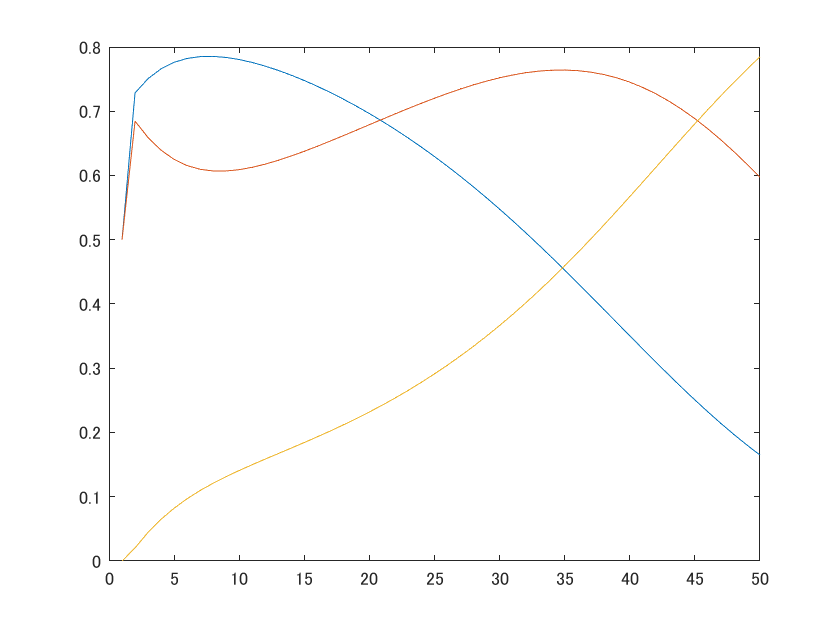

n = 50;
pops = zeros(3, n);

v = [0.5, 0.5, 0];
pops(:, 1) = v';

m = 0.18057;
k = 0.6;
b = 0.4;

for i = 2 : n
    v = (1 - m) * v;
    pp = k * (v * P1 * v') * b + v(1);
    pq = k * (v * P2 * v') * b + v(2);
    qq = k * 1.4 * (v * P3 * v') * b + v(3);
    v = [pp, pq, qq];
    v = v / norm(v);
    pops(:, i) = v';
end

figure;
plot(pops(1, :));
hold on
plot(pops(2, :));
plot(pops(3, :));
hold off